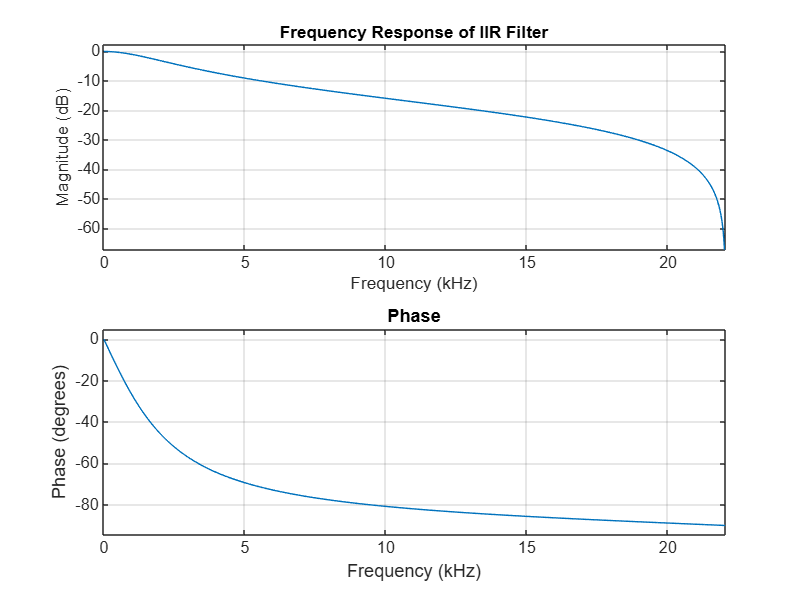

% Clear workspace, figures and command window
clear;
close all;
clc;

% Read the audio file - returns audio data and sampling frequency
[inputSignal, fs] = audioread('noisysignal.wav');

% Set filter parameters
filterOrder = 50;                          % Order of the filter
cutoffFreq = 1000;                         % Cutoff frequency in Hz
normalizedCutoff = cutoffFreq / (fs/2);    % Normalize c
% 0utoff frequency by Nyquist rate
% Step 3: Design IIR Butterworth Filter
% order=1;
% [b_iir, a_iir] = butter(order, normalizedCutoff);

% Chebyshev Type I Filter
% order=1;
% ripple = 1;
% [b_iir, a_iir] = cheby1(order, ripple, normalizedCutoff);

% Elliptic Filter Design
order = 1;                                 % Filter order
ripplePass = 1;                            % Passband ripple in dB
rippleStop = 40;                           % Stopband attenuation in dB
[b_iir, a_iir] = ellip(order, ripplePass, rippleStop, normalizedCutoff);

% Plot frequency response of the filter
figure;
freqz(b_iir, a_iir, 1024, fs);
title('Frequency Response of IIR Filter');


% Apply the filter to the input signal
filteredSignal = filter(b_iir, a_iir, inputSignal);

% Play the original audio
disp('Playing Original Noisy Audio...');

Playing Original Noisy Audio...


sound(inputSignal, fs);
pause(length(inputSignal)/fs + 1);

% Play the filtered audio
disp('Playing Filtered Audio (IIR)...');

Playing Filtered Audio (IIR)...


sound(filteredSignal, fs);
pause(length(filteredSignal)/fs + 1);

% Save the filtered audio
audiowrite('filteredSignalIIR.wav', filteredSignal, fs);